s0_add_paths;

## The loss landscape

% parameters
target = 'target'; ds = 2; roi = 1; n = 5;
model = oriSurroundModel(); model_idx = 3;
fit_param = dataloader(stdnormRootPath, 'param', target, ds, roi, 'noCross', model_idx, 'fmincon');
fit_param

fit_param =     0.0714    0.0000   11.9391


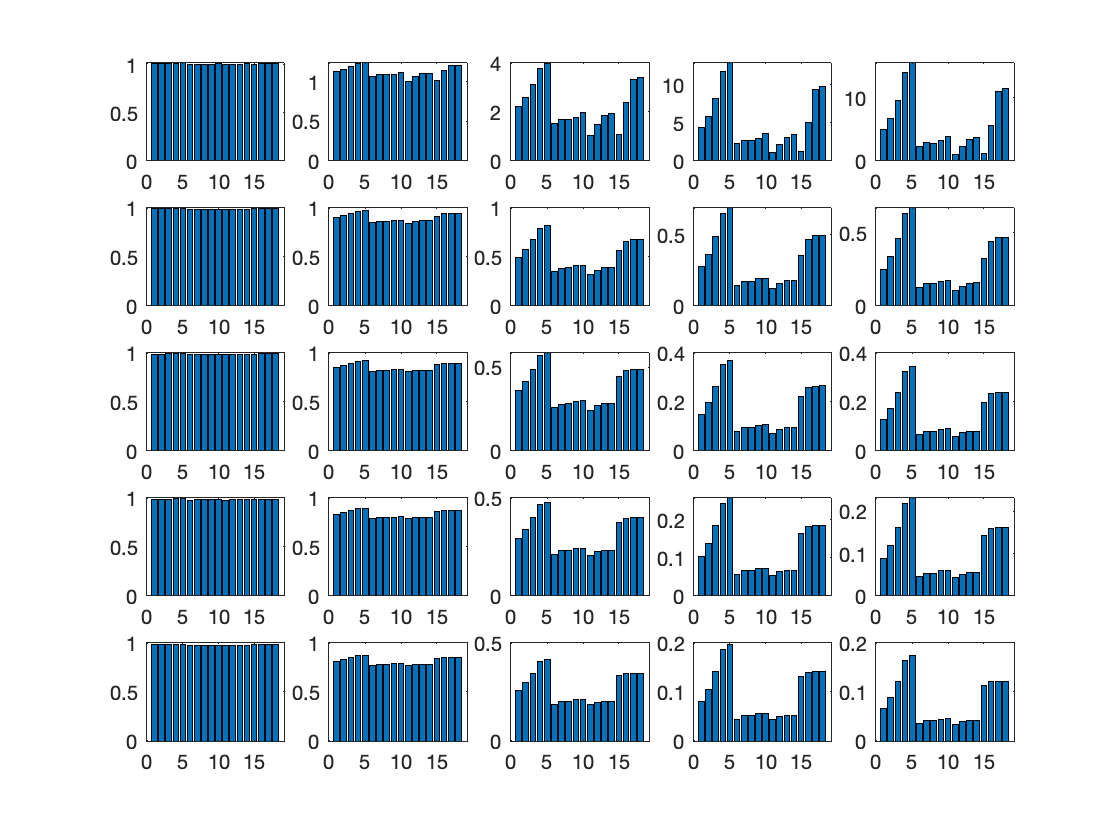

wLst = linspace(.01, 1, n);
nLst = linspace(-5, 5, n);
mse_land = nan(n, n);

% input 
E = dataloader(stdnormRootPath, 'E_xy', target, ds, roi);
Z = dataloader(stdnormRootPath, 'Z1', target, ds, roi);

% output 
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target', target, ds, roi); 
for i = 1:n
    for j = 1:n
        subplot(n, n, n*(i-1)+j)
        fit_param(1) = wLst(i);
        fit_param(3) = nLst(j);
        BOLD_hat = model.forward(model, E, Z, fit_param);
        bar(BOLD_hat)
%         mse = double(mean((BOLD_tar - BOLD_hat).^2));
%         mse_land(i, j) = mse;
    end
end

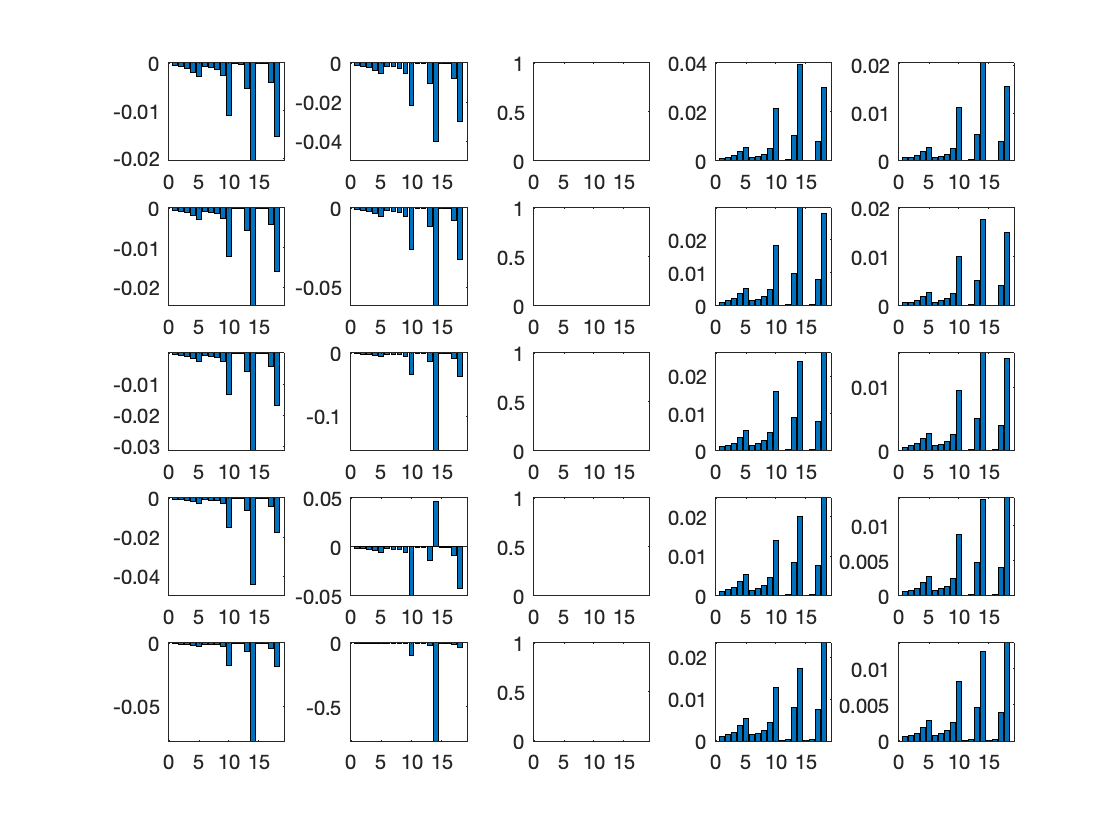

fit_param = [0, 0, 3];
wLst = linspace(.01, 1, n);
bLst = linspace(-5, 5, n);
mse_land = nan(n, n);

% input 
E = dataloader(stdnormRootPath, 'E_xy', target, ds, roi);
Z = dataloader(stdnormRootPath, 'Z1', target, ds, roi);

% output 
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target', target, ds, roi); 
for i = 1:n
    for j = 1:n
        subplot(n, n, n*(i-1)+j)
        fit_param(1) = wLst(i);
        fit_param(2) = bLst(j);
        BOLD_hat = model.forward(model, E, Z, fit_param);
        bar(BOLD_hat)
%         mse = double(mean((BOLD_tar - BOLD_hat).^2));
%         mse_land(i, j) = mse;
    end
end

param = [0.1, .2, .2];
BOLD_hat = model.forward(model, E, Z, param);
mse = double(mean((BOLD_tar - BOLD_hat).^2))

mse = 1.2254

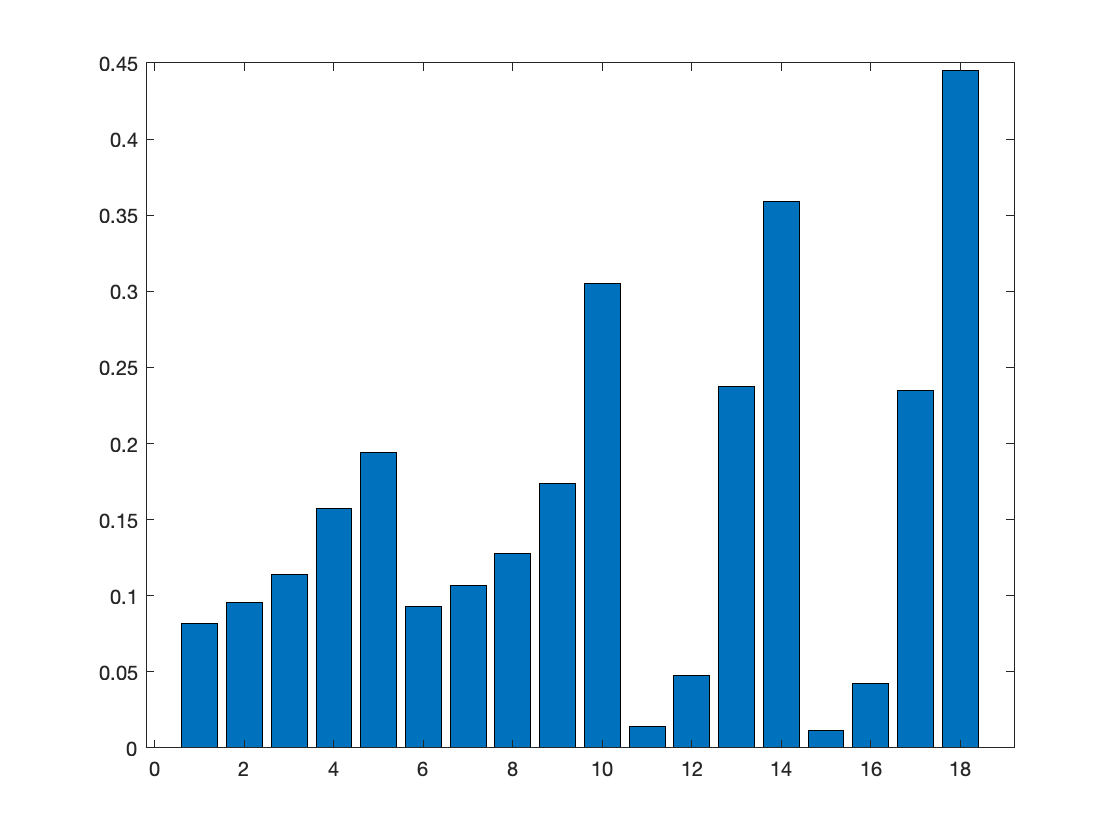

bar(BOLD_hat)

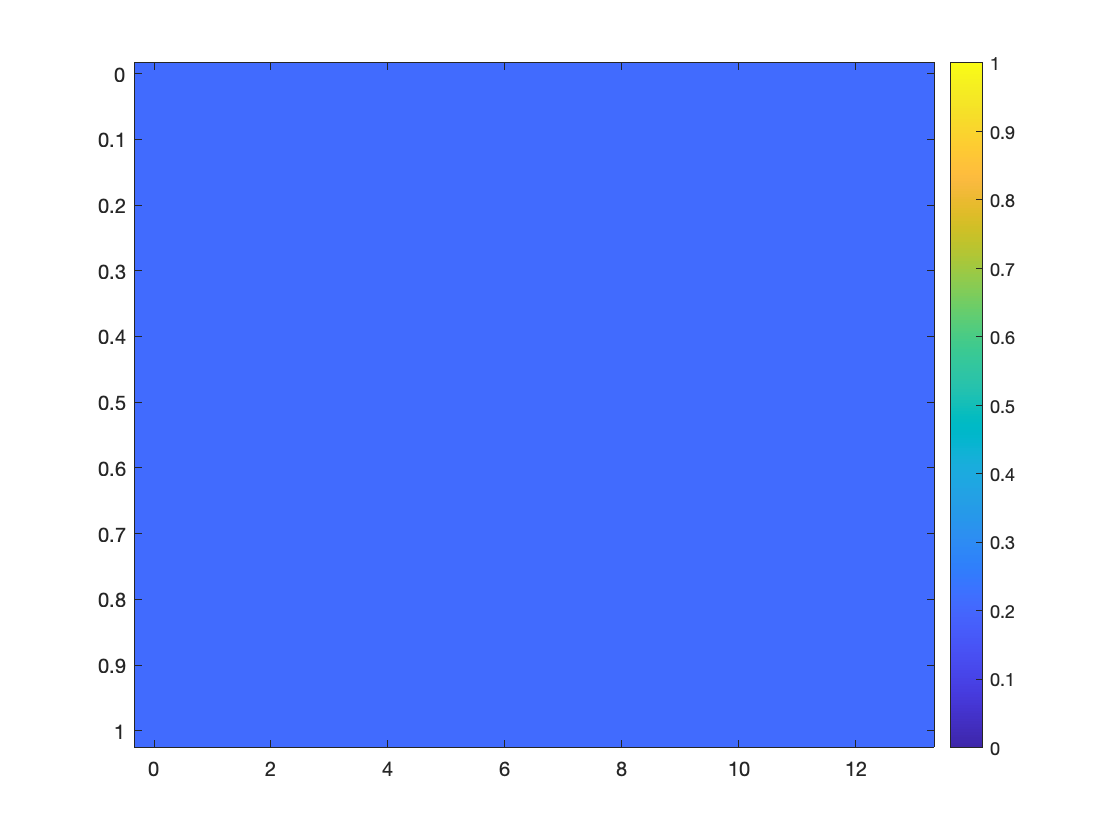

% visualize 
mse_land(imag(mse_land) ~= 0) = inf;
figure();
imagesc(nLst, wLst, mse_land,[0, 1]);
colorbar;

min(mse_land(:))

ans = 0.2110